# Calculation of Fourier coefficients for Square Wave

Prepared for EG-247 Signals and Systems by Chris Jobling

syms t n A pi

n = [1:11];

## DC component

half_a0 = 1/(2*pi)*(int(A,t,0,pi)+int(-A,t,pi,2*pi))

$$half\_a0 = 0$$

## Compute harmonics

ai = 1/pi*(int(A*cos(n*t),t,0,pi)+int(-A*cos(n*t),t,pi,2*pi))

$$ai = \left(\begin{array}{ccccccccccc} \frac{A\,\sin\left(\pi \right)-A\,\sin\left(\pi \right)\,\left(2\,\cos\left(\pi \right)-1\right)}{\pi } & \frac{\frac{A\,\sin\left(2\,\pi \right)}{2}+\frac{A\,\sin\left(2\,\pi \right)\,\left(4\,{\sin\left(\pi \right)}^{2}-1\right)}{2}}{\pi } & \frac{\frac{A\,\sin\left(3\,\pi \right)}{3}+\frac{A\,\left(\sin\left(3\,\pi \right)-\sin\left(6\,\pi \right)\right)}{3}}{\pi } & \frac{\frac{A\,\sin\left(4\,\pi \right)}{4}+\frac{A\,\left(\sin\left(4\,\pi \right)-\sin\left(8\,\pi \right)\right)}{4}}{\pi } & \frac{\frac{A\,\sin\left(5\,\pi \right)}{5}+\frac{A\,\left(\sin\left(5\,\pi \right)-\sin\left(10\,\pi \right)\right)}{5}}{\pi } & \frac{\frac{A\,\sin\left(6\,\pi \right)}{6}+\frac{A\,\left(\sin\left(6\,\pi \right)-\sin\left(12\,\pi \right)\right)}{6}}{\pi } & \frac{\frac{A\,\sin\left(7\,\pi \right)}{7}+\frac{A\,\left(\sin\left(7\,\pi \right)-\sin\left(14\,\pi \right)\right)}{7}}{\pi } & \frac{\frac{A\,\sin\left(8\,\pi \right)}{8}+\frac{A\,\left(\sin\left(8\,\pi \right)-\sin\left(16\,\pi \right)\right)}{8}}{\pi } & \frac{\frac{A\,\sin\left(9\,\pi \right)}{9}+\frac{A\,\left(\sin\left(9\,\pi \right)-\sin\left(18\,\pi \right)\right)}{9}}{\pi } & \frac{\frac{A\,\sin\left(10\,\pi \right)}{10}+\frac{A\,\left(\sin\left(10\,\pi \right)-\sin\left(20\,\pi \right)\right)}{10}}{\pi } & \frac{\frac{A\,\sin\left(11\,\pi \right)}{11}+\frac{A\,\left(\sin\left(11\,\pi \right)-\sin\left(22\,\pi \right)\right)}{11}}{\pi } \end{array}\right)$$

bi = 1/pi*(int(A*sin(n*t),t,0,pi)+int(-A*sin(n*t),t,pi,2*pi))

$$bi = \left(\begin{array}{ccccccccccc} -\frac{A\,\left(\cos\left(\pi \right)-1\right)-A\,\left(\cos\left(\pi \right)-1\right)\,\left(2\,\cos\left(\pi \right)+1\right)}{\pi } & \frac{A\,{\sin\left(\pi \right)}^{2}+A\,{\sin\left(\pi \right)}^{2}\,\left(4\,{\sin\left(\pi \right)}^{2}-3\right)}{\pi } & -\frac{A\,\left(\frac{\cos\left(3\,\pi \right)}{3}-\frac{\cos\left(6\,\pi \right)}{3}\right)-\frac{2\,A\,{\sin\left(\frac{3\,\pi }{2}\right)}^{2}}{3}}{\pi } & -\frac{A\,\left(\frac{\cos\left(4\,\pi \right)}{4}-\frac{\cos\left(8\,\pi \right)}{4}\right)-\frac{A\,{\sin\left(2\,\pi \right)}^{2}}{2}}{\pi } & -\frac{A\,\left(\frac{\cos\left(5\,\pi \right)}{5}-\frac{\cos\left(10\,\pi \right)}{5}\right)-\frac{2\,A\,{\sin\left(\frac{5\,\pi }{2}\right)}^{2}}{5}}{\pi } & -\frac{A\,\left(\frac{\cos\left(6\,\pi \right)}{6}-\frac{\cos\left(12\,\pi \right)}{6}\right)-\frac{A\,{\sin\left(3\,\pi \right)}^{2}}{3}}{\pi } & -\frac{A\,\left(\frac{\cos\left(7\,\pi \right)}{7}-\frac{\cos\left(14\,\pi \right)}{7}\right)-\frac{2\,A\,{\sin\left(\frac{7\,\pi }{2}\right)}^{2}}{7}}{\pi } & -\frac{A\,\left(\frac{\cos\left(8\,\pi \right)}{8}-\frac{\cos\left(16\,\pi \right)}{8}\right)-\frac{A\,{\sin\left(4\,\pi \right)}^{2}}{4}}{\pi } & -\frac{A\,\left(\frac{\cos\left(9\,\pi \right)}{9}-\frac{\cos\left(18\,\pi \right)}{9}\right)-\frac{2\,A\,{\sin\left(\frac{9\,\pi }{2}\right)}^{2}}{9}}{\pi } & -\frac{A\,\left(\frac{\cos\left(10\,\pi \right)}{10}-\frac{\cos\left(20\,\pi \right)}{10}\right)-\frac{A\,{\sin\left(5\,\pi \right)}^{2}}{5}}{\pi } & -\frac{A\,\left(\frac{\cos\left(11\,\pi \right)}{11}-\frac{\cos\left(22\,\pi \right)}{11}\right)-\frac{2\,A\,{\sin\left(\frac{11\,\pi }{2}\right)}^{2}}{11}}{\pi } \end{array}\right)$$

Reconstruct $f\left(t\right)$ from harmonic sine functions

ft = half_a0;
for k=1:length(n)
    ft = ft + ai(k)*cos(k*t) + bi(k)*sin(k*t);
end
ft

## Make numeric

ft_num = subs(ft,A,1.0)

print using 4 sig digits

ft_num = vpa(ft_num, 4)

plot result

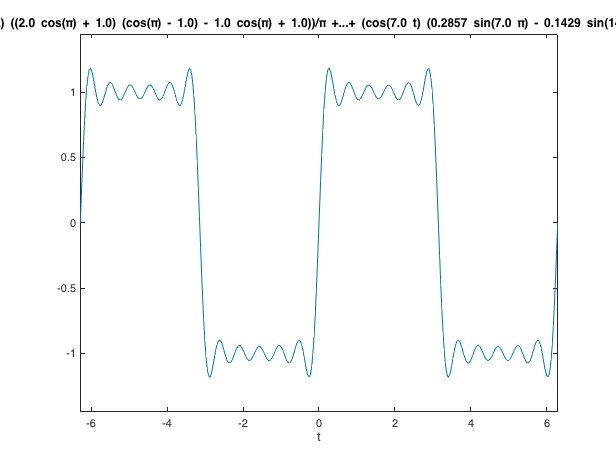

ezplot(ft_num)
hold on

## Ovelay original signal onto plot

(we could use `heaviside` for this as well)

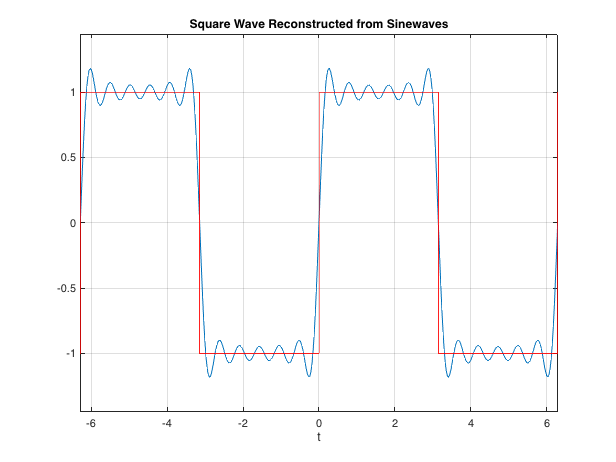

clear pi % need pi to be numeric
t = [-3,-2,-2,-2,-1,-1,-1,0,0,0,1,1,1,2,2,2,3]*pi;
f = [-1,-1,0,1,1,0,-1,-1,0,1,1,0,-1,-1,0,1,1];
plot(t,f,'r-')
grid
title('Square Wave Reconstructed from Sinewaves')
hold off